clear
% Step 1
% Mean Gaussian = 0
% Variance Gaussian = sigma^2

mu = 0;
sigma = sqrt(2);
M = 100;

data = normrnd(mu, sigma, 1, M);

disp('Random Gaussian Distribution:');

Random Gaussian Distribution:


disp(data);

    0.6926    0.0837   -0.7623   -0.5005    0.0303   -0.0246   -0.6542   -0.6389    0.3625    0.1608    0.1294   -1.4150   -1.0714   -1.0357   -0.3791    0.7536    1.6110   -3.4703    1.7458   -2.4744    1.7046   -3.2639    0.9458   -1.3320   -0.0640    1.6281   -1.8365   -1.6015   -0.6773   -0.8681   -0.1772    1.3938    2.0115    0.4501   -2.8818    0.7446    1.0316   -0.7321   -0.2900   -0.9199   -0.3091    1.2294    1.1729    0.7936   -2.4644    0.2347   -0.9496   -0.0098   -2.5843   -0.9066    2.8711    1.0294   -0.1177   -0.1076   -1.3432   -1.3843    2.3635    0.8394    1.7481    0.8175   -0.0889    2.5635   -0.7493   -1.5754    0.4285   -0.4583    1.5609   -1.8532   -1.3088    1.0569    0.5546    2.8959    0.4697    0.6620   -0.9292   -1.5886   -1.0521   -0.2706    0.7008   -2.7302    0.4273   -0.7625    1.2510    1.6032    0.0535    0.8800    2.7582   -2.2420    1.7085   -1.5085   -0.2017   -0.3197   -2.1075   -0.0664   -0.8468    0.1588   -0.3933    2.4559   -0.2847    1.1845

% Step 2

mu_s = mean(data);      % Sample Mean of Data
sigma_s = std(data);    % Sample Standard Deviation of Data

disp(['Sample Mean: ', num2str(mu_s)]);

Sample Mean: -0.066318


disp(['Sample Standard Deviation: ', num2str(sigma_s)]);

Sample Standard Deviation: 1.3947


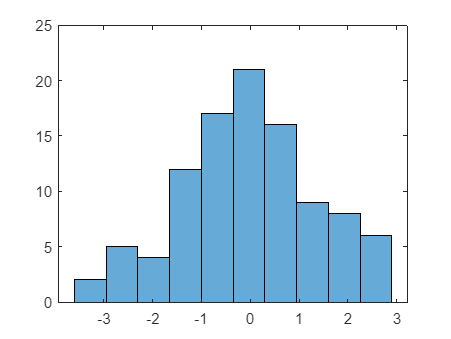

% Step 3

K = 10;
h = histogram(data, K);

mj = h.Values;                                  % # Samples In Each Bin
Cj = h.BinEdges(1:end-1) + diff(h.BinEdges)/2;  % Centers Of Each Bin

disp('Bin Samples (mj):');

Bin Samples (mj):


disp(mj);

     2     5     4    12    17    21    16     9     8     6



disp('Bin Centers (Cj):');

Bin Centers (Cj):


disp(Cj);

   -3.2750   -2.6250   -1.9750   -1.3250   -0.6750   -0.0250    0.6250    1.2750    1.9250    2.5750



% Step 4

delta = (Cj(end) - Cj(1)) / (K - 1);    % (End Bin - Start Bin) / # Gaps

disp(['Bin Length Delta: ', num2str(delta)]);

Bin Length Delta: 0.65


% Step 5

simulated_pdf = mj / (M * delta);   % Directly From Lab Procedure

disp('Simulated pdf at Bin Centers:');

Simulated pdf at Bin Centers:


disp(simulated_pdf);

    0.0308    0.0769    0.0615    0.1846    0.2615    0.3231    0.2462    0.1385    0.1231    0.0923



% Step 6

numerator = -((Cj - mu_s).^2);          % Numerator
denominator = 2 * sigma_s^2;            % Denominator
scalar = 1 / (sigma_s * sqrt(2*pi));    % Scalar / Front Value?

theoretical_pdf = scalar * exp(numerator / denominator);

disp('Theoretical pdf at Bin Centers:');

Theoretical pdf at Bin Centers:


disp(simulated_pdf);

    0.0308    0.0769    0.0615    0.1846    0.2615    0.3231    0.2462    0.1385    0.1231    0.0923



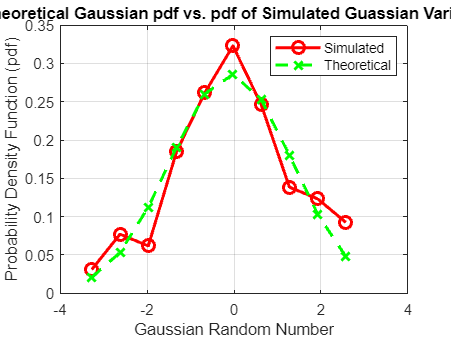

% Step 7

figure;
plot(Cj, simulated_pdf, 'r-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

plot(Cj, theoretical_pdf, 'g-x', 'LineStyle', '--', 'LineWidth', 2, 'MarkerSize', 8);

xlabel('Gaussian Random Number');
ylabel('Probability Density Function (pdf)');
title('Theoretical Gaussian pdf vs. pdf of Simulated Guassian Variates');
legend('Simulated', 'Theoretical');

grid on;
hold off;